# fitlm Anwendungen

Die nachfolgenden Beispiele sollen verwendet werden, um die Verwendung von fitlm zu üben. Die Beispiele stammen aus ganz unterschiedlichen Anwendungsgebieten. Sie geben einen kleinen Einblick in die vielfältigen Einsatzmöglichkeiten dieser Methode.

## Energieverbrauch für das Heizen von Wasser

In einem Schüler-Praktikum wurde diese Messsung gemacht um die spezifische Wärmekapazität des Wassers zu bestimmen. (Leider sind die Einheiten nicht überliefert :-( 

***fitlm_daten\EnergieH2oTemp.csv***

Machen Sie eine Analyse mit fitlm

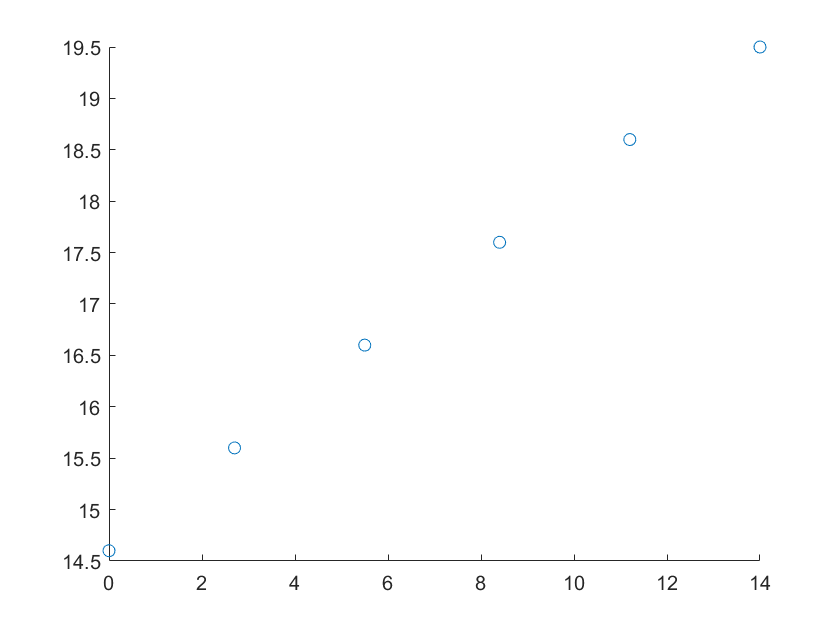

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = [ "Energy", "Temperature"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
H2O_Heizen = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\EnergieH2oTemp.csv", opts);
scatter(H2O_Heizen.Energy, H2O_Heizen.Temperature);

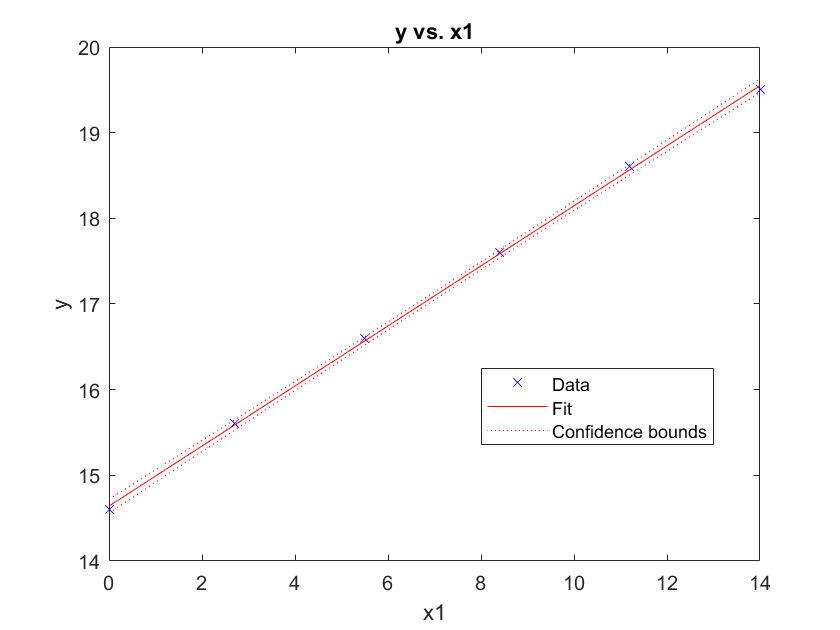

fit = fitlm(H2O_Heizen.Energy, H2O_Heizen.Temperature);
plot(fit);

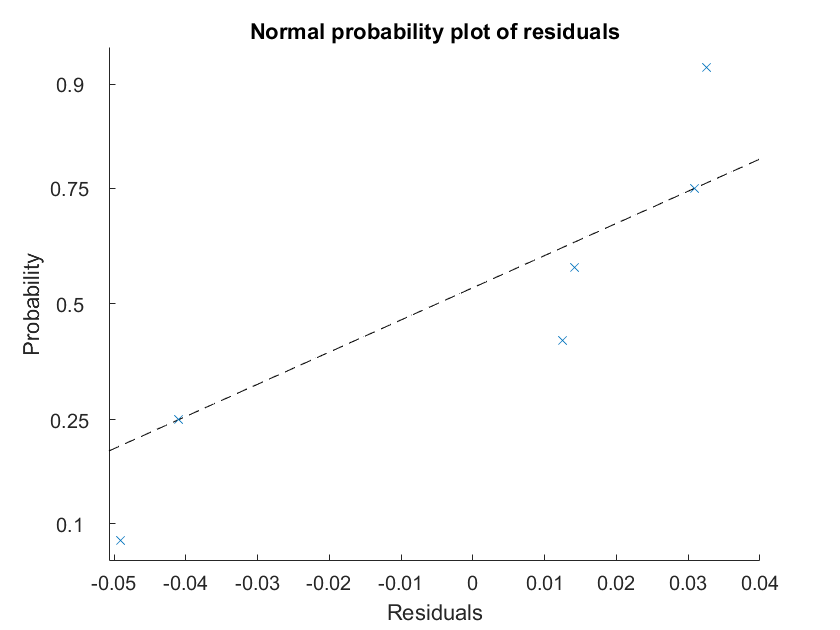

plotResiduals(fit,"probability");

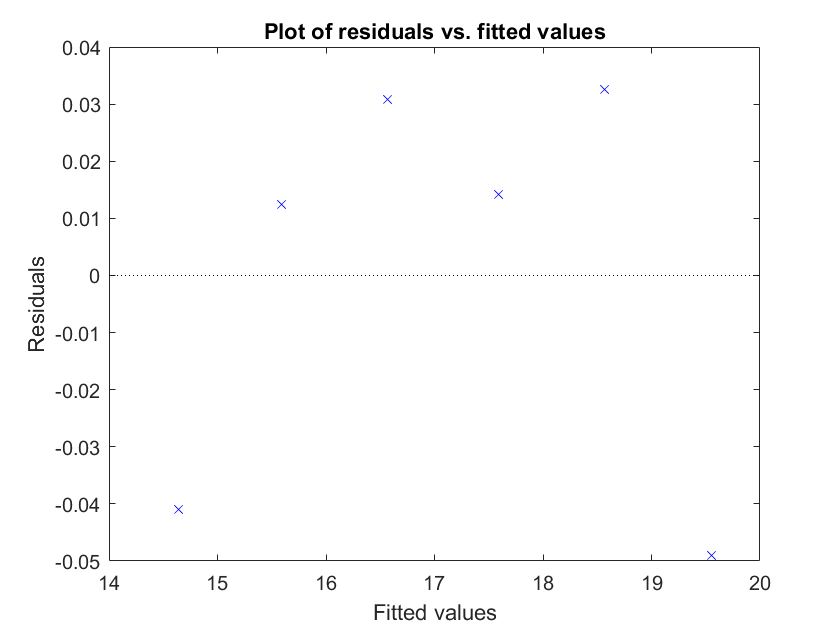

plotResiduals(fit,"fitted");

## Laufgeschwindigkeit vs. Herzfrequenz

In einem Fittnesstest wurden nachfolgende Daten aufgezeichnet: ***fitlm_daten\Conconi.csv***

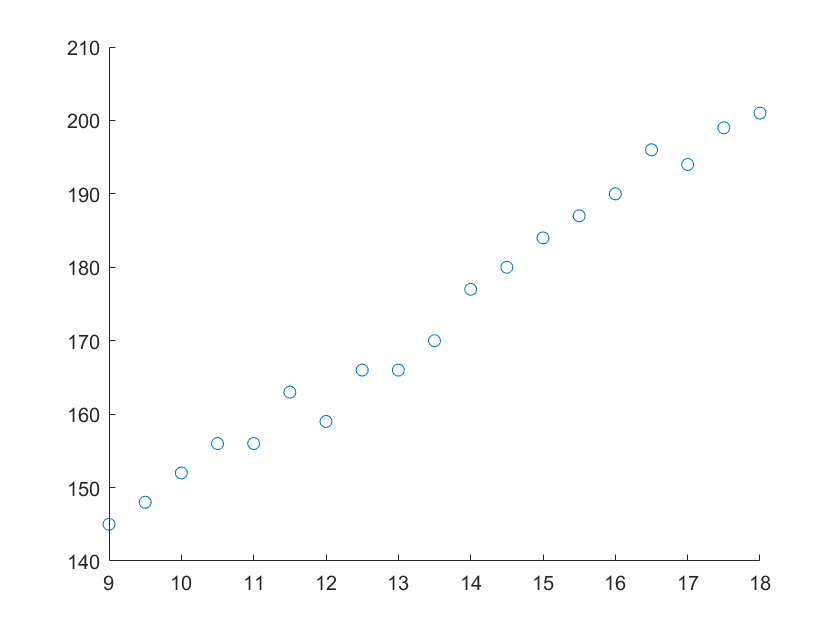

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Row", "Speed", "Puls"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
conconi = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\Conconi.csv", opts);
scatter(conconi.Speed, conconi.Puls);

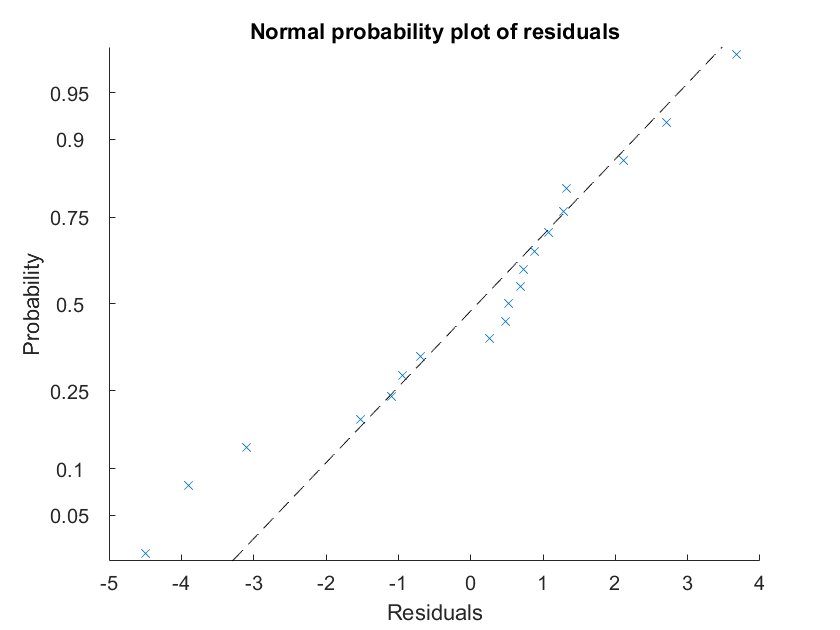

fitC = fitlm(conconi.Speed, conconi.Puls);
plotResiduals(fitC,"probability");

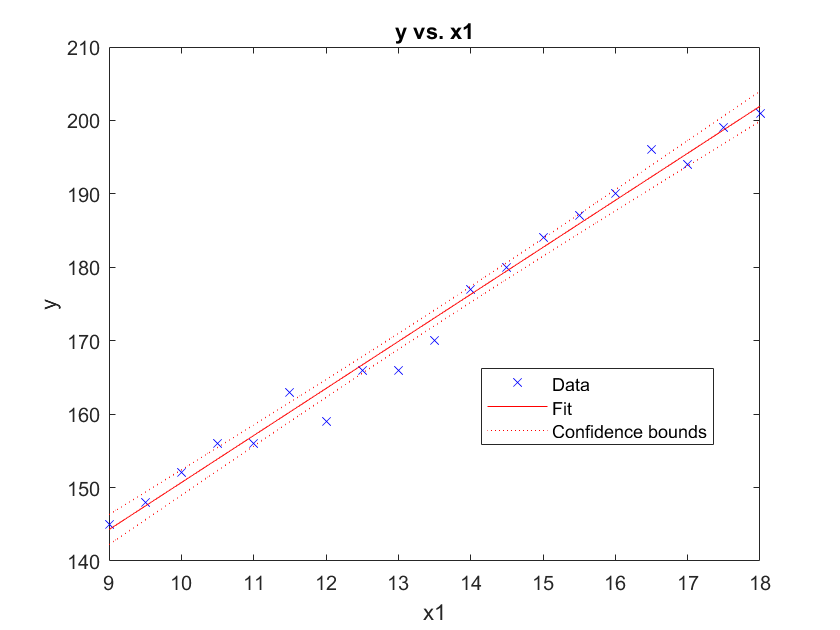

plot(fitC);

## Zusammenhang Alter zu Preis bei Antiken Uhren

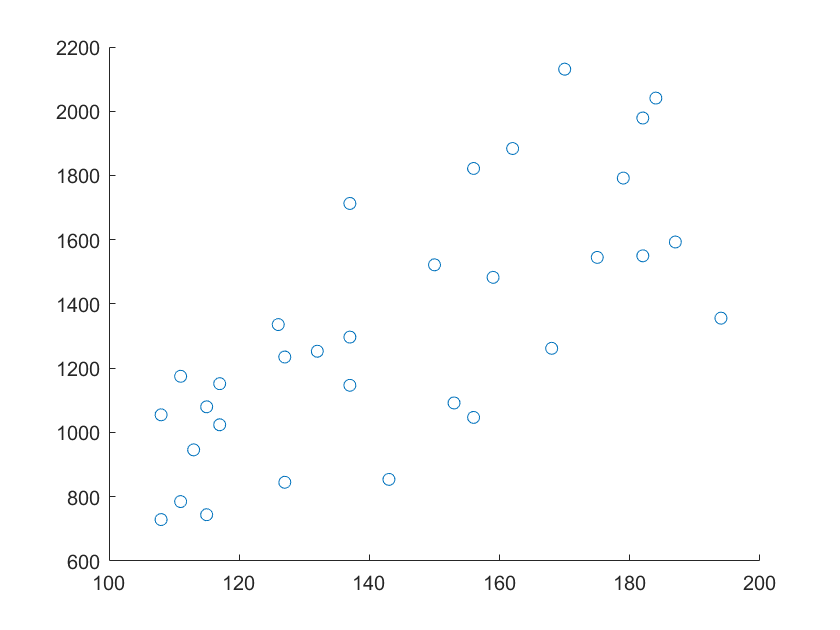

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "Alter", "Preis"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
antikeUhren = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\antikeUhren.csv", opts);
scatter(antikeUhren.Alter, antikeUhren.Preis);

fitAU = fitlm(antikeUhren, "Preis~Alter")

fitAU = Linear regression model:
    Preis ~ 1 + Alter

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)    -191.66     263.89    -0.72629       0.47329
    Alter           10.479       1.79      5.8543    2.0965e-06


Number of observations: 32, Error degrees of freedom: 30
Root Mean Squared Error: 273
R-squared: 0.533,  Adjusted R-Squared: 0.518
F-statistic vs. constant model: 34.3, p-value = 2.1e-06

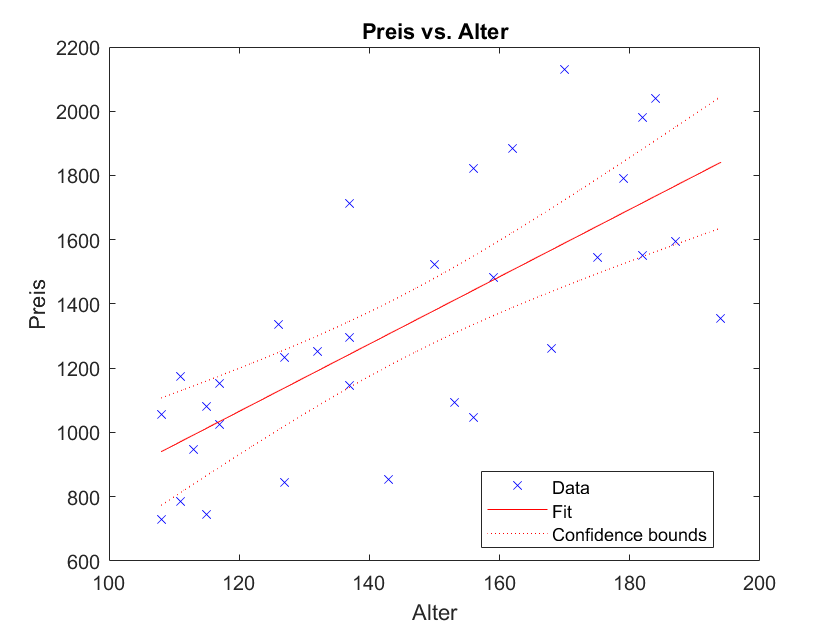


plot(fitAU);

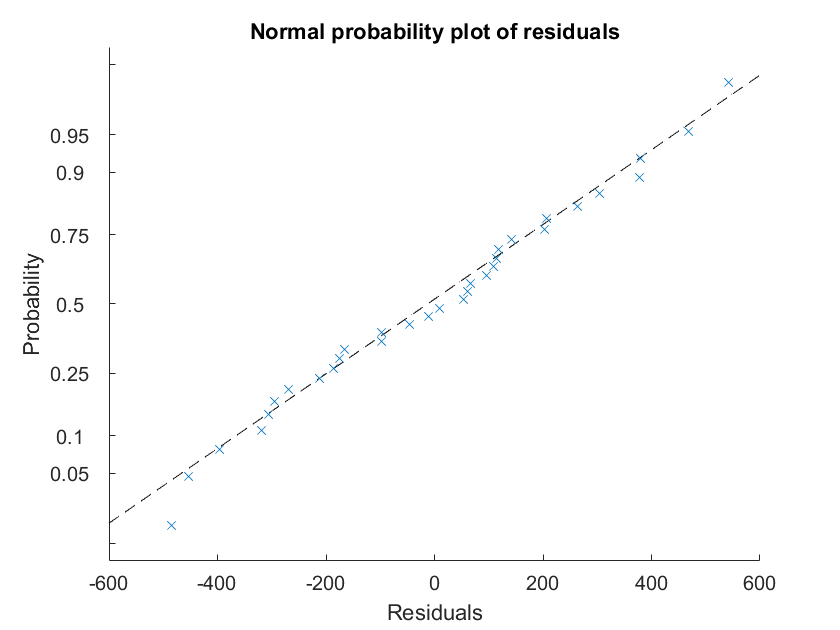

plotResiduals(fitAU,"probability");

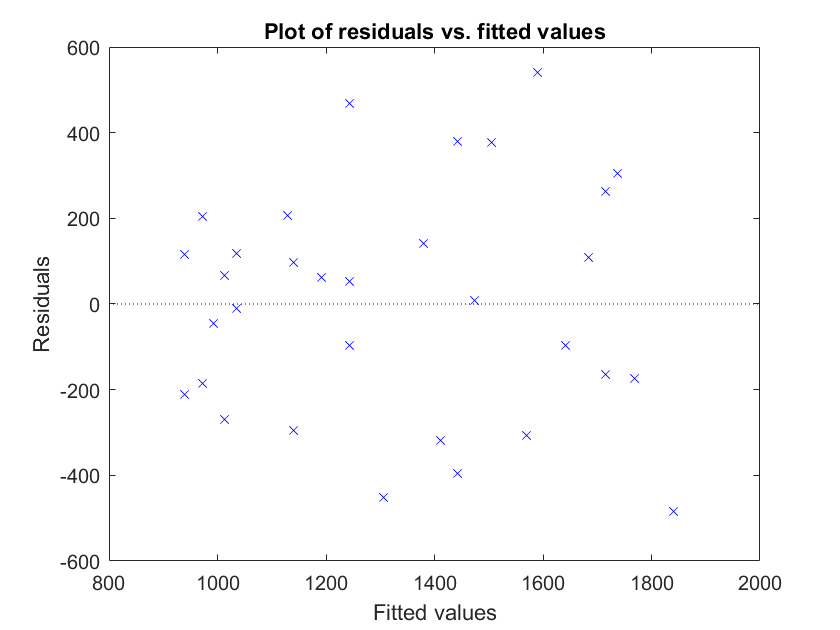

plotResiduals(fitAU,"fitted");

## Zusammenhang Temperatur-Differenz Aussen/Innen zu Verbrauch

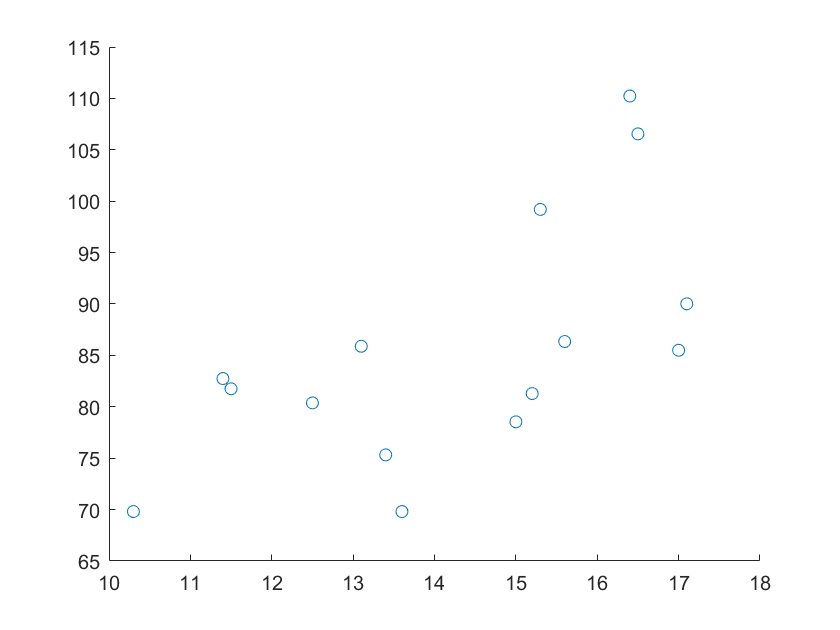

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "temp", "verbrauch"];
opts.VariableTypes = ["int16", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
TempVsUsage = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\gas.csv", opts);

scatter(TempVsUsage.temp, TempVsUsage.verbrauch);


fitTU = fitlm(TempVsUsage, "verbrauch~temp")

fitTU = Linear regression model:
    verbrauch ~ 1 + temp

Estimated Coefficients:
                   Estimate      SE      tStat      pValue 
                   ________    ______    ______    ________

    (Intercept)     36.894     16.961    2.1752    0.048658
    temp            3.4127     1.1766    2.9005    0.012397


Number of observations: 15, Error degrees of freedom: 13
Root Mean Squared Error: 9.6
R-squared: 0.393,  Adjusted R-Squared: 0.346
F-statistic vs. constant model: 8.41, p-value = 0.0124

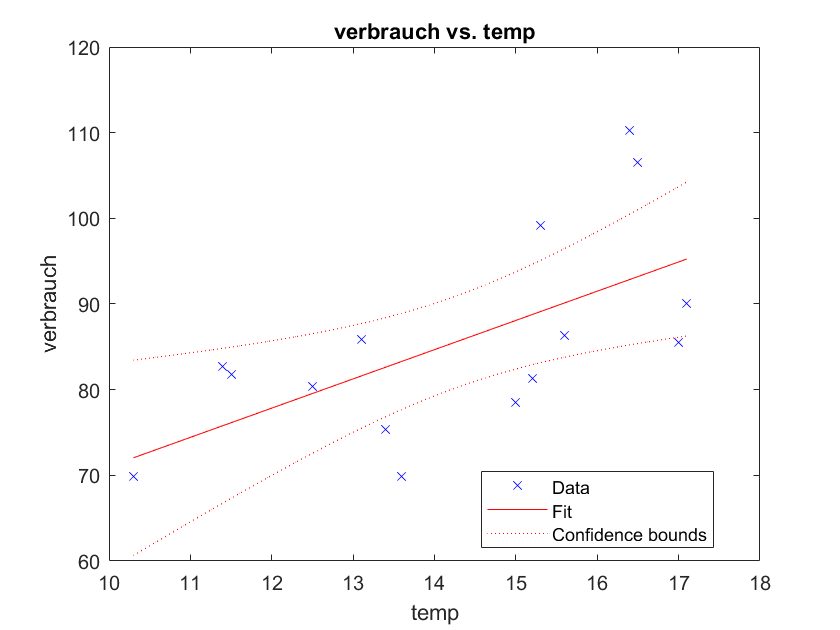


plot(fitTU);

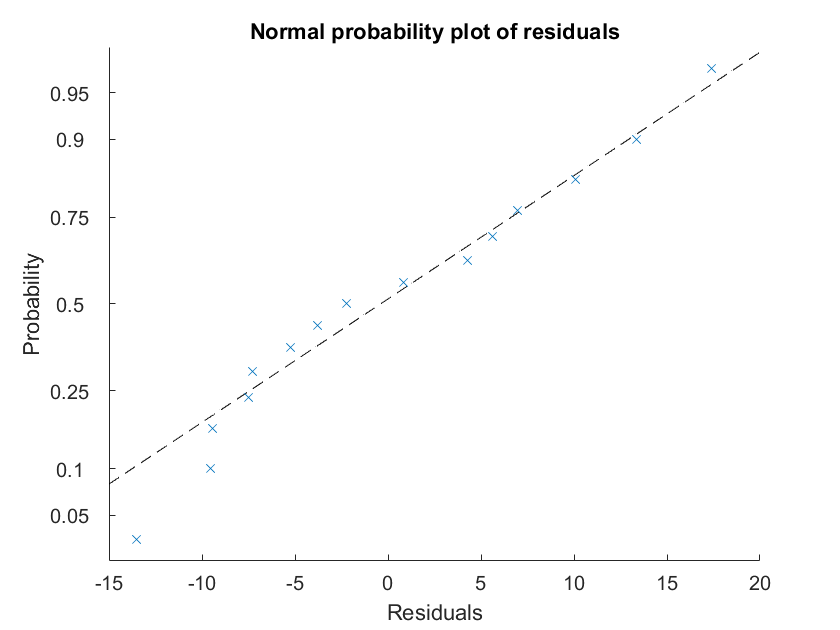

plotResiduals(fitTU,"probability");

### Wodurch wird der Benzin-Verbrauch von Autos pro 100 km beeinflusst?

Welche Prediktoren scheinen Ihnen glaubhaft? Versuchen Sie aus. 

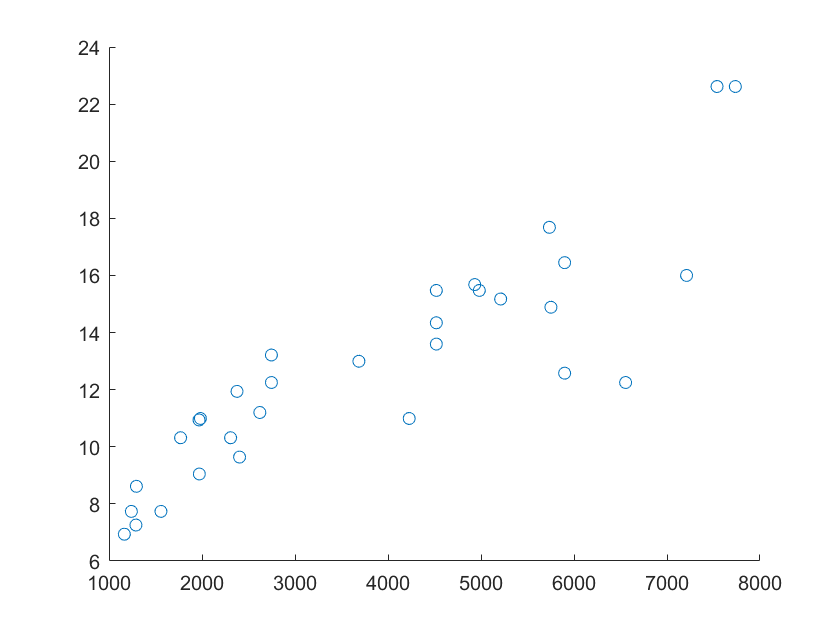

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "L_100km", "hubraum", "cyl", "ps", "drat", "wt", "qsec", "vs", "am", "gear", "carb"];
opts.VariableTypes = ["int16", "double", "double","double", "double", "double", "double", "double", "categorical","categorical","categorical","categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
HpVsFuel = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\ps_benzin.csv", opts);
scatter(HpVsFuel.hubraum, HpVsFuel.L_100km);

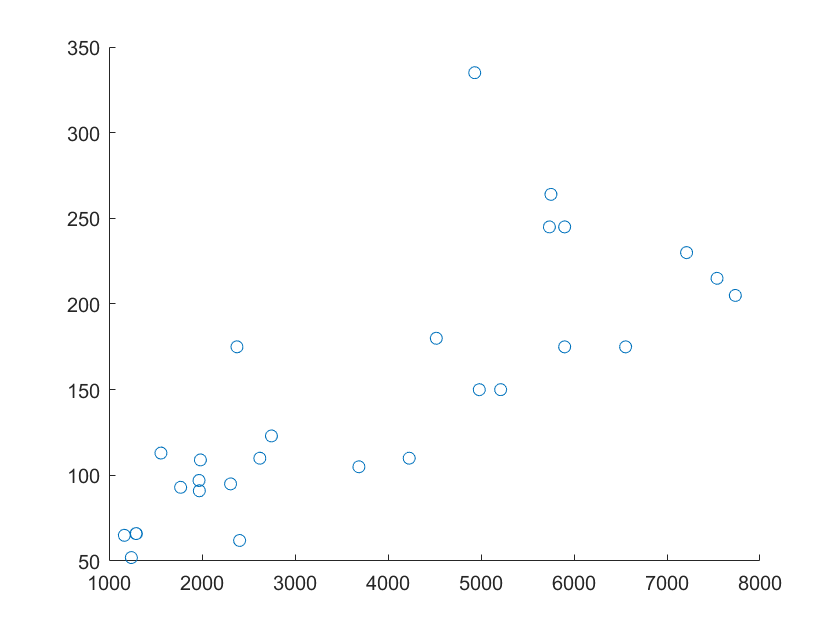

scatter(HpVsFuel.hubraum, HpVsFuel.ps);

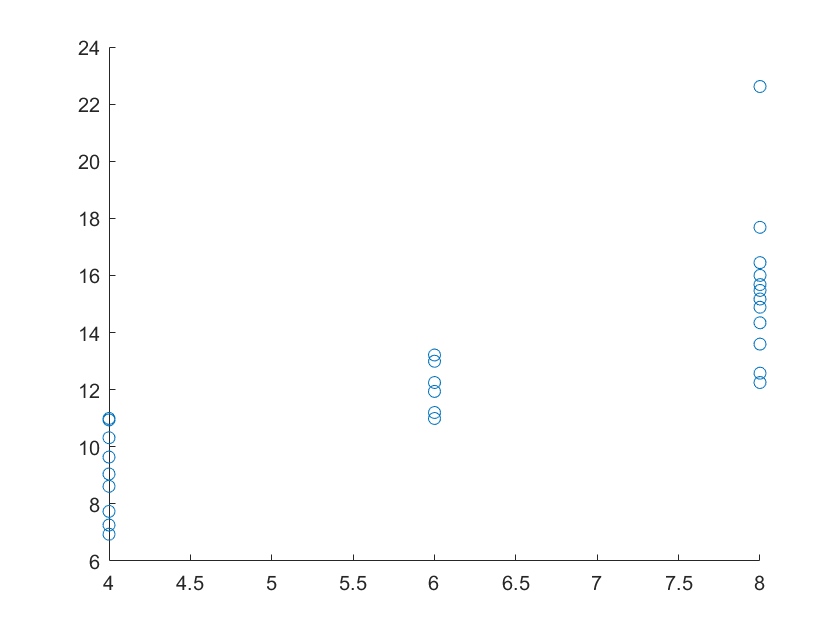

scatter(HpVsFuel.cyl, HpVsFuel.L_100km);

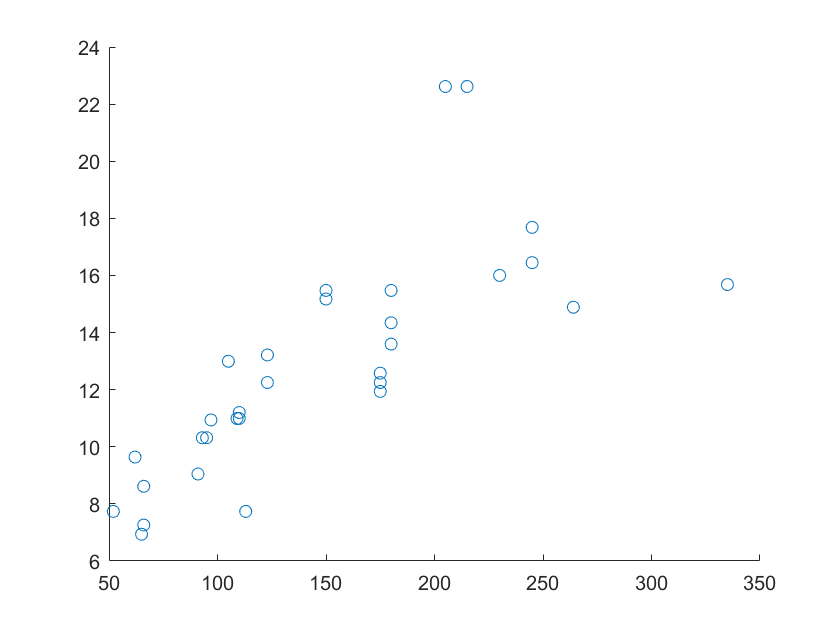

scatter(HpVsFuel.ps, HpVsFuel.L_100km);

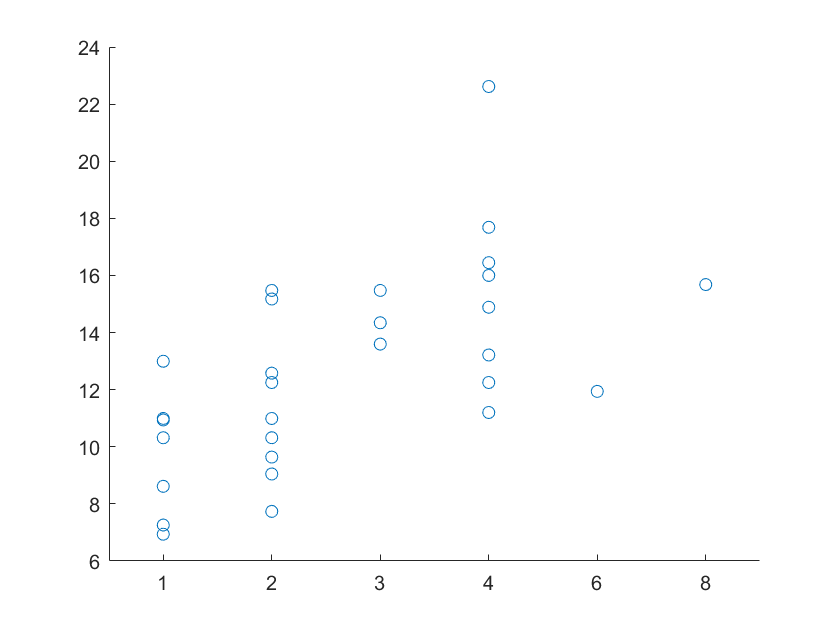

scatter(HpVsFuel.carb, HpVsFuel.L_100km);


fitFuel = fitlm(HpVsFuel,"L_100km~hubraum")

fitFuel = Linear regression model:
    L_100km ~ 1 + hubraum

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       6.4276       0.70595    9.1049    3.8769e-10
    hubraum        0.0016736    0.00016506    10.139    3.3161e-11


Number of observations: 32, Error degrees of freedom: 30
Root Mean Squared Error: 1.87
R-squared: 0.774,  Adjusted R-Squared: 0.767
F-statistic vs. constant model: 103, p-value = 3.32e-11

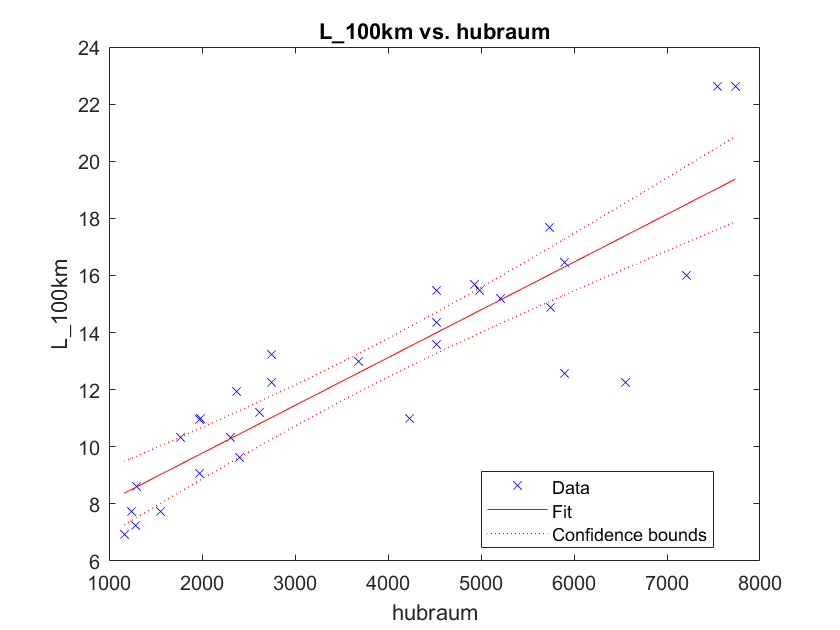

plot(fitFuel);

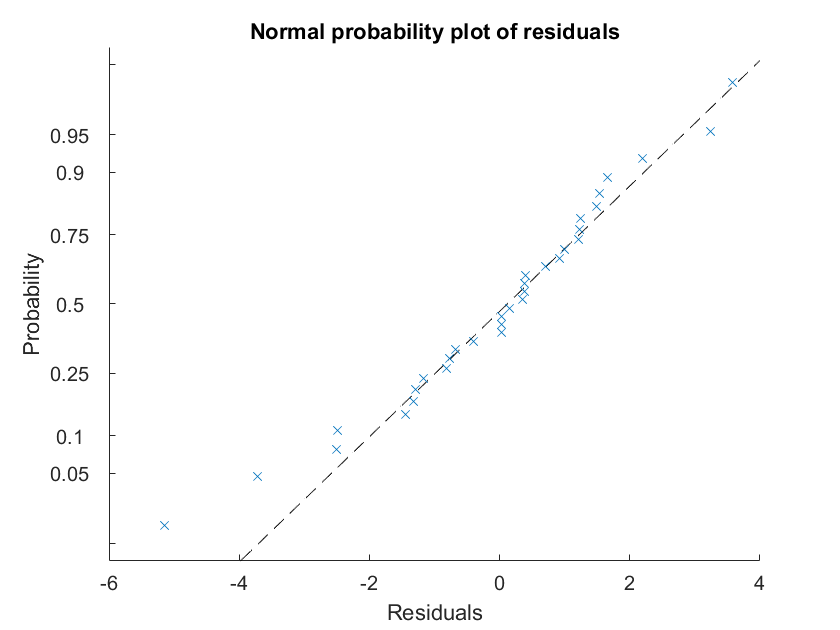

plotResiduals(fitFuel,"probability");

## Ozongehalt im Zusammenhang mit Sonneneinstrahlung, Temperatur und Wind

%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Observation", "Ozone", "Solar_R", "Wind", "Temp", "Month", "Day"];
opts.VariableTypes = ["int16", "double", "double", "double", "double", "categorical", "int16"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Ozone", "Solar_R"], "EmptyFieldRule", "auto");

% Import the data
airquality = readtable("C:\Users\Ioannis\Desktop\GitHub\MATLAB\linear_regression\data\airquality.csv", opts);

model = fitlm([airquality.Temp, airquality.Wind, airquality.Solar_R], airquality.Ozone)

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -64.342      23.055    -2.7908     0.0062266
    x1               1.6521     0.25353     6.5164    2.4235e-09
    x2              -3.3336     0.65441    -5.0941    1.5159e-06
    x3             0.059821    0.023186       2.58      0.011237


Number of observations: 111, Error degrees of freedom: 107
Root Mean Squared Error: 21.2
R-squared: 0.606,  Adjusted R-Squared: 0.595
F-statistic vs. constant model: 54.8, p-value = 1.51e-21

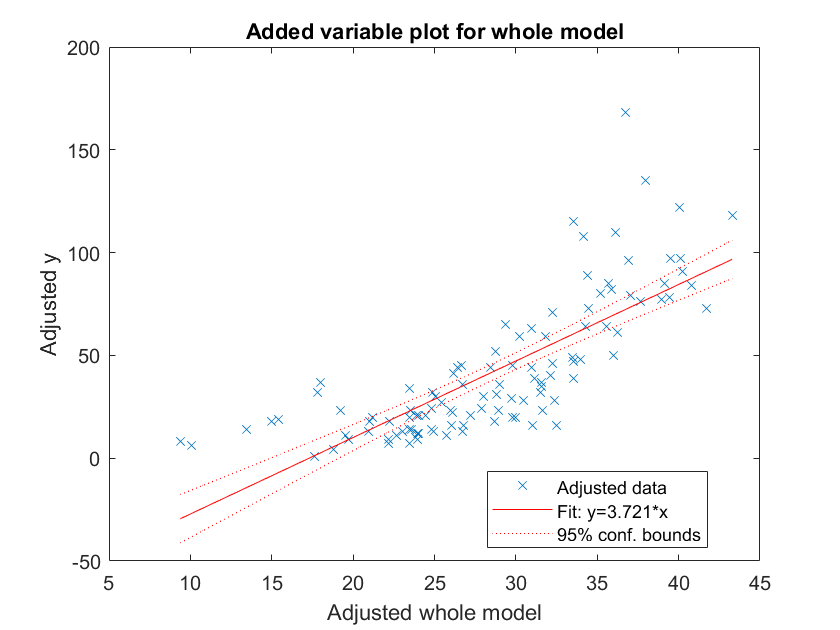

plot(model);

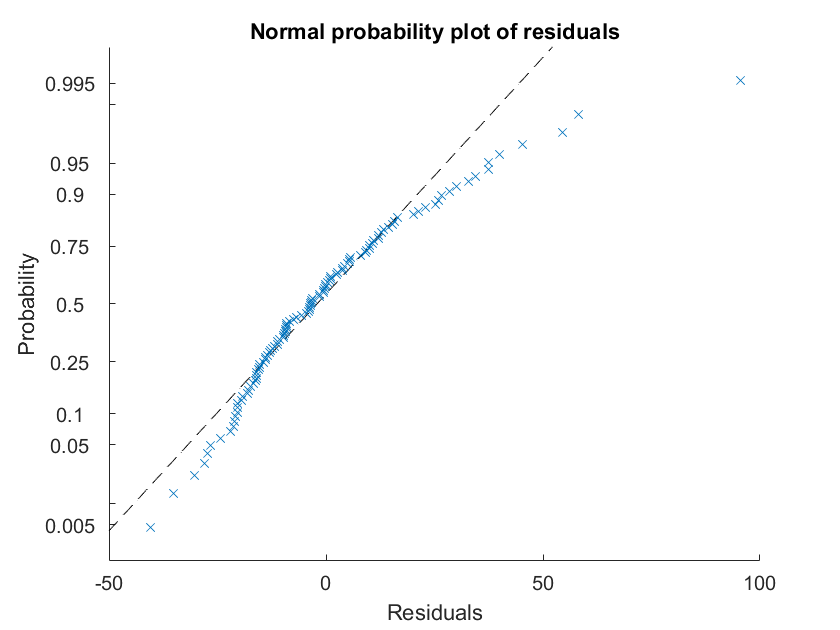

plotResiduals(model,"probability");